### **Q1: MAXQUAD**

**Preliminary**

**First we specify the required parameters and define the oracle.**

%% parameters
clear;clc;
d = 10;
K = 5;
opt(K) = struct();
x1 = ones(d,1);

%% Create optimization oracles
[I,J] = meshgrid(1:d, 1:d);
for k = 1:K
    A = zeros(d);
    b = zeros(1, d);
    [J, I] = meshgrid(1:d, 1:d);
    A = exp(I./J) .* cos(I.*J) .* sin(k);
    A(I>=J) = 0;
    A = (A + A');
    A = A + diag(abs(sin(k)/10.*(1:d)') + sum(abs(A), 2));
    b = exp((1:d)'/k) .* sin((1:d)'*k);
    opt(k).A = A;
    opt(k).b = b;
end

#### Part 1

%% evaluating initial point
fx1 = oracle_f(x1, opt, K);
fprintf("Q1 Part 1: \n");

Q1 Part 1: 


fprintf("The initial objective value is: %5.4f \n\n", fx1);

The initial objective value is: 5337.0664 



#### Part 2

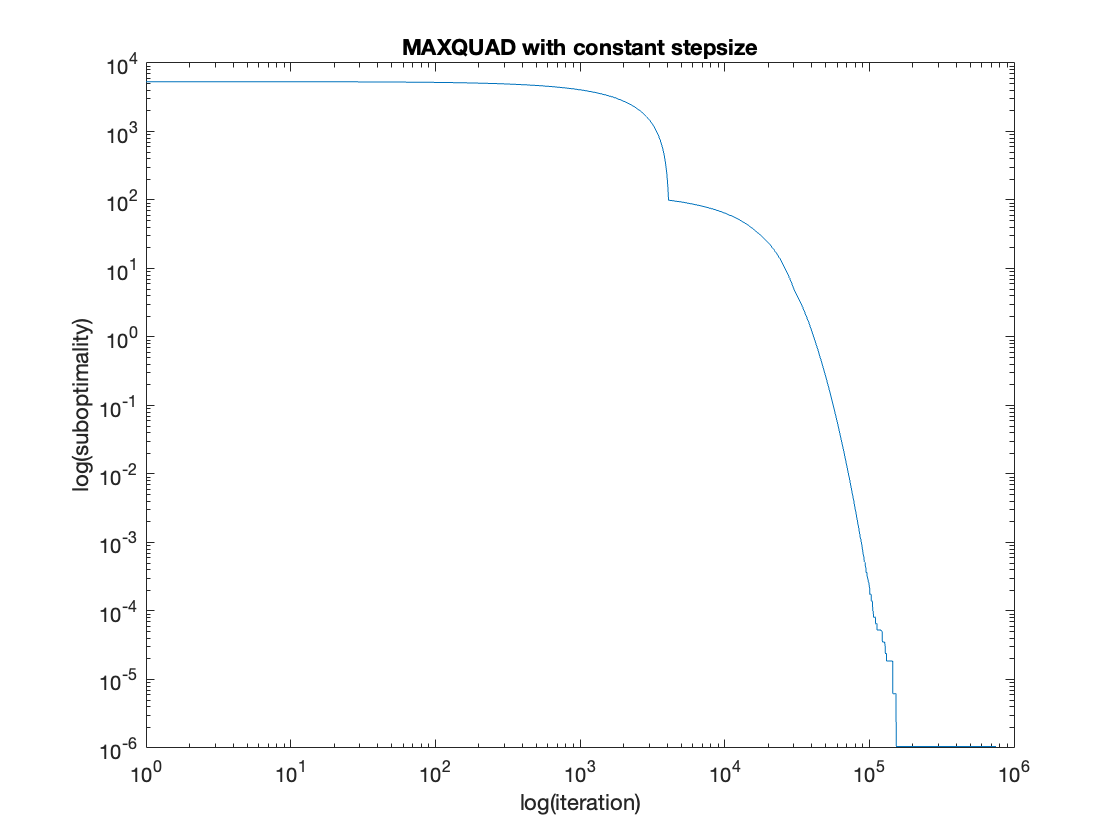

%% finding optimal value: full-batch stepsize

T = 1e6; C = 0.1; epsilon = 1e-6;
eta = C/sqrt(T);
xt  = x1;
[fxt, gxt]     =  oracle_f(xt, opt, K);
best_so_far    =  zeros(T,1);
best_so_far(1) =  fxt;

for t = 2:T
    % if mod(t, 1e4) == 0
    %   disp(["Running iteration: ", num2str(t)]);
    % end
    xt = xt - eta * gxt/norm(gxt);
    [fxt, gxt] = oracle_f(xt, opt, K);
    if (fxt < best_so_far(t-1) - epsilon)
        best_so_far(t) = fxt;
    else
        best_so_far(t) = best_so_far(t-1);
    end
end

best_gap = best_so_far - best_so_far(T);
loglog(1:T, best_gap);
title("MAXQUAD with constant stepsize");
xlabel('log(iteration)');
ylabel('log(suboptimality)');

fprintf('\n');

#### Part 3

From the results we can see constant stepsize requires a long procedure for burning in, and the suboptimality does not closely follow the theoretical behavior implied by the upper bound(which should be approximately linear on a log-log plot). On the contrary, Boris-Polyak stepsize gives updates that smoothly decreases and aligns better with the theoretical trend.

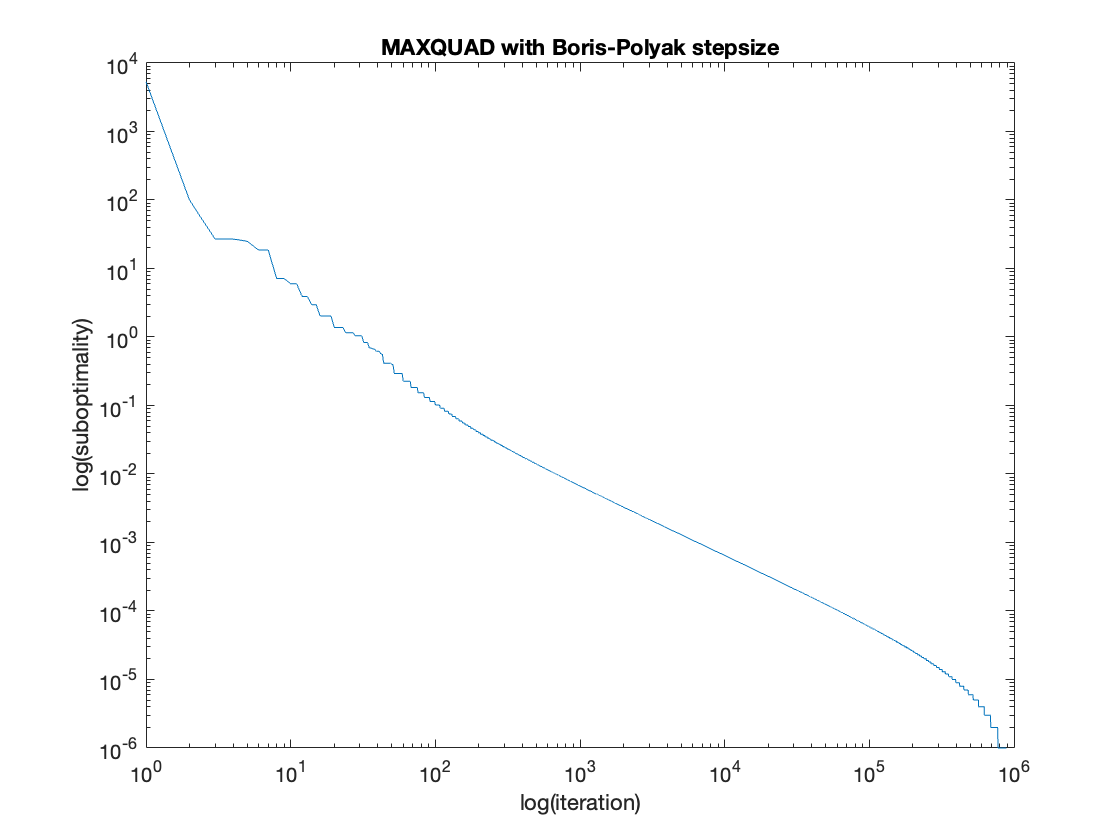

%% finding optimal value: Boris-Polyak stepsize
T = 1e6; C = 1; epsilon = 1e-6;
xt = x1;
[fxt, gxt] =  oracle_f(xt, opt, K);
best_so_far_bp    = zeros(T,1);
best_so_far_bp(1) = fxt;
fmin = best_so_far(T);

for t = 2:T
    % if mod(t, 1e4) == 0
    %  disp(["Running iteration: ", num2str(t)]);
    % end
    eta = (fxt - fmin) / norm(gxt);  
    xt  = xt - eta * gxt / norm(gxt);
    [fxt, gxt] =  oracle_f(xt, opt, K);
    if (fxt < best_so_far_bp(t-1) - epsilon)
        best_so_far_bp(t) = fxt;
    else
        best_so_far_bp(t) = best_so_far_bp(t-1);
    end
end
best_gap_bp = best_so_far_bp - best_so_far_bp(T);
loglog(1:T, best_gap_bp);
title("MAXQUAD with Boris-Polyak stepsize");
xlabel('log(iteration)');
ylabel('log(suboptimality)');

function [fx, gx] = oracle_f(x, opt, K)
   obj = zeros(K,1);
   for k = 1:K
       obj(k) = x' * opt(k).A * x - x' * opt(k).b; 
   end
   [fx, ind]  =  max(obj);
   gx = 2 .* opt(ind).A * x - opt(ind).b;
end